# A dataset of EEG signals related to upper and lower limb execution of motor and motor imagery tasks

#### by Victor Asanza:

- `Repository: `[`https://github.com/Human-Machine-Interface/OpenBCI_Classification_Example`](https://github.com/Human-Machine-Interface/OpenBCI_Classification_Example)

- `When using this code you must download the Mendeley dataset into the ``MILimbEEG`` folder: `[http://dx.doi.org/10.17632/w9xfz56txv.2](http://dx.doi.org/10.17632/w9xfz56txv.2)

- Hardware: FM=16 chanels , Cyton + Dasy , Campling Rate = 125 Hz

- Subjects: 24

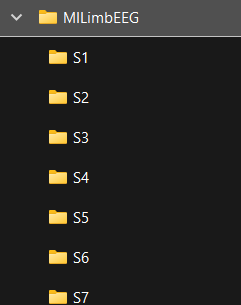

**All Labels:**

- *(Sx + Rx + Ix + _n) or (Sn + Rn + Mn + _n), example: S2R1I1_0*

- *Sx: such that x can be any number from 1 to 60.*

- *Rx: Number of times the entire experiment was repeated. Such that x can be any repetition number between 1 and 4.*

- *M: motor tasks. I: imagery tasks.*

- *1 is for ****BEO****, 2 for ****CLH****, 3 for ****CRH****, 4 for ****DLF****, 5 for ****PLF****, 6 for ****DRF****, 7 for ****PRF**** and finally 8 for ****Rest.***

- ***_n: ****Ordinal number of the task repetition. Number of times each task is repeated.*

**Relevant information:**

- `Data was collected using the following repository: `[`https://github.com/vasanza/OpenBCI`](https://github.com/vasanza/OpenBCI)

- Code for real-time detection: [https://github.com/vasanza/BCI_Motor_Imagery_Task_OpenBCI](https://github.com/vasanza/BCI_Motor_Imagery_Task_OpenBCI)

- `This dataset (MILimbEEG) was published in the following journal:: `[`https://www.sciencedirect.com/science/article/pii/S2352340923006406?via%3Dihub`](https://www.sciencedirect.com/science/article/pii/S2352340923006406?via%3Dihub)

**Pending tasks:**

- Take stratified samples of the class of interest (2 and 3) and the Rest class (8), from line 3 of the code

- Testing new additional features to rms from line 30 of the code

# Raw dataset preparation

clear;clc;%clear all
addpath(genpath('./src'))%functions folders
path = fullfile('./MILimbEEG/');%data folder
folders = FindFolders(path);
allData=[];

# Motor tasks of interest

**Right upper limb (RH) classification algorithms:**

- *Sx: such that x can be any number from 1 to 60.*

- *Rx: Number of times the entire experiment was repeated. Such that x can be any repetition number between 1 and 4.*

- *M: motor tasks. I: imagery tasks.*

- *3 for ****CRH****, and finally 8 for ****Rest.***

- ***_n: ****Ordinal number of the task repetition. Number of times each task is repeated.*

% List of allowed values
% allowed_values = {'M3','M8'}; pattern = 'M(\d+)'; % M: motor tasks
% allowed_values = {'I3','I8'}; pattern = 'I(\d+)'; % I: imagery tasks

**Left upper limb (LH) classification algorithms:**

- *Sx: such that x can be any number from 1 to 60.*

- *Rx: Number of times the entire experiment was repeated. Such that x can be any repetition number between 1 and 4.*

- *M: motor tasks. I: imagery tasks.*

- *2 for ****CLH****, and finally 8 for ****Rest.***

- ***_n: ****Ordinal number of the task repetition. Number of times each task is repeated.*

% List of allowed values
% allowed_values = {'M2','M8'}; pattern = 'M(\d+)'; %M: motor tasks
% allowed_values = {'I2','I8'}; pattern = 'I(\d+)'; % I: imagery tasks

**Right and Left upper limb (RH & LH) classification algorithms:**

- *Sx: such that x can be any number from 1 to 60.*

- *Rx: Number of times the entire experiment was repeated. Such that x can be any repetition number between 1 and 4.*

- *M: motor tasks. I: imagery tasks.*

- *3 for ****CRH****, and finally 8 for ****Rest.***

- ***_n: ****Ordinal number of the task repetition. Number of times each task is repeated.*

% List of allowed values
% allowed_values = {'M2','M3','M8'}; pattern = 'M(\d+)'; %M: motor tasks
allowed_values = {'I2','I3','I8'}; pattern = 'I(\d+)'; % I: imagery tasks

# Raw dataset preprocessing

#### % In this example no filtering was done, but it can be done

for i=1:length(folders)% Through all folders
    path1=fullfile(path,folders(i).name);%Select i folder
    filenames = FindCSV(path1);%List All CSV files
    for j=1:length(filenames)% Through all files
        % Extract the code using regexp
        result = regexp(filenames(j).name, pattern, 'match');
        if ~isempty(result)
            code_M = result{1}; % Get the found code, e.g., 'M1'
            if any(strcmp(code_M, allowed_values))
                data=readtable(fullfile(path1,filenames(j).name));%Select i CSV file
                dataNew=table2array(data);% Array Double
                dataNew(1,:)=[];%Delete the first row
                dataNew(:,1)=[];%Delete the first column
                DataNorm = fNormalization(dataNew);%Normalization
                Label = str2num(result{1}(2));%fLabelEEG(filenames(j).name);
                DataRMS = [rms(DataNorm) Label];%Feature extraction
                allData=[allData;DataRMS];
                
                % If you want to generate graphs with the EEG data
                %filename=strcat('./figures/',strcat(int2str(i),'_',strcat(int2str(j),strcat('_',num2str(Label)))));
                %fPlotEEG(dataNew,filename);
                %filename=strcat('./figuresNorm/',strcat(int2str(i),'_',strcat(int2str(j),strcat('_',num2str(Label)))));
                %fPlotEEG(DataNorm,filename);            
            end
        end
    end
end
%Save .CSV file with all EEG file features
csvwrite('AllDataRMS.csv',allData);

# Plot Raw EEG dataset

figure
plot(dataNew);xlabel('Samples');ylabel('mVolts');

Unrecognized function or variable 'dataNew'.

title('Raw EEG data graph');
legend('Electrode 1','Electrode 2','Electrode 3','Electrode 4','Electrode 5'...
    ,'Electrode 6','Electrode 7','Electrode 8','Electrode 9','Electrode 10'...
    ,'Electrode 11','Electrode 12','Electrode 13','Electrode 14','Electrode 15','Electrode 16');

# Plot Normalization EEG dataset

figure
plot(DataNorm);xlabel('Samples');ylabel('Normalized Values');
title('Normalized EEG data graph');
legend('Electrode 1','Electrode 2','Electrode 3','Electrode 4','Electrode 5'...
    ,'Electrode 6','Electrode 7','Electrode 8','Electrode 9','Electrode 10'...
    ,'Electrode 11','Electrode 12','Electrode 13','Electrode 14','Electrode 15','Electrode 16');

# Statistical information of rms in EEG dataset

Electrode_1 = datastats(allData(:,1))%RMS Electrode 1
Electrode_2 = datastats(allData(:,2))%RMS Electrode 2
Electrode_3 = datastats(allData(:,3))%RMS Electrode 3
Electrode_4 = datastats(allData(:,4))%RMS Electrode 4
Electrode_5 = datastats(allData(:,5))%RMS Electrode 5
Electrode_6 = datastats(allData(:,6))%RMS Electrode 6
Electrode_7 = datastats(allData(:,7))%RMS Electrode 7
Electrode_8 = datastats(allData(:,8))%RMS Electrode 8
Electrode_9 = datastats(allData(:,9))%RMS Electrode 9
Electrode_10 = datastats(allData(:,10))%RMS Electrode 10
Electrode_11 = datastats(allData(:,11))%RMS Electrode 11
Electrode_12 = datastats(allData(:,12))%RMS Electrode 12
Electrode_13 = datastats(allData(:,13))%RMS Electrode 13
Electrode_14 = datastats(allData(:,14))%RMS Electrode 14
Electrode_15 = datastats(allData(:,15))%RMS Electrode 15
Electrode_16 = datastats(allData(:,16))%RMS Electrode 16

# Feature Selection

DataFeatures=allData(:,1:16);
%corrplot(DataNorm)
R = corrcoef(DataFeatures)

# **Classification of movement in the right upper extremity (RH):**

clear;clc;
% Upload .CSV file with the features of all EEG files
path = fullfile('./MILimbEEG/');%data folder
%allData = fLoad_EEG_csv(path,'AllDataRMS_motor_RH.csv');
allData = fLoad_EEG_csv(path,'AllDataRMS_imagery_RH.csv');

classificationLearner


# allowed_values = {'M3','M8'}; % M: motor tasks

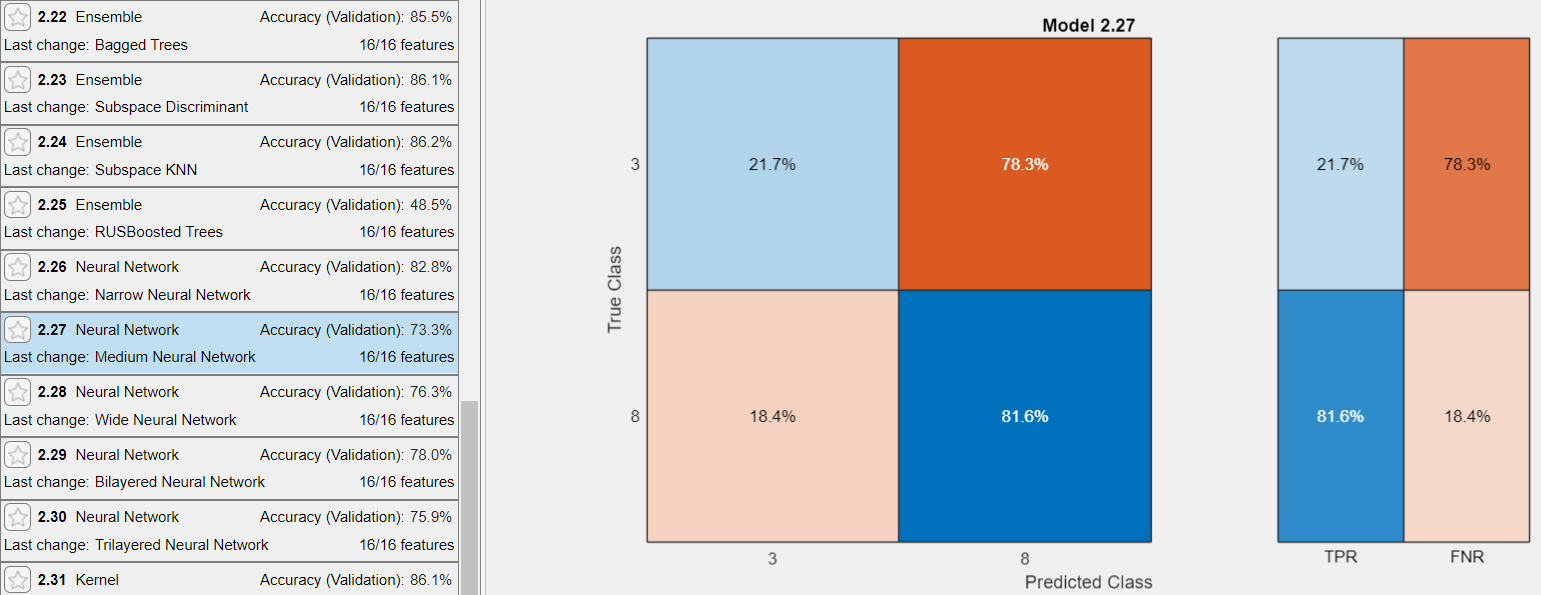

# allowed_values = {'I3','I8'}; % I: imagery tasks

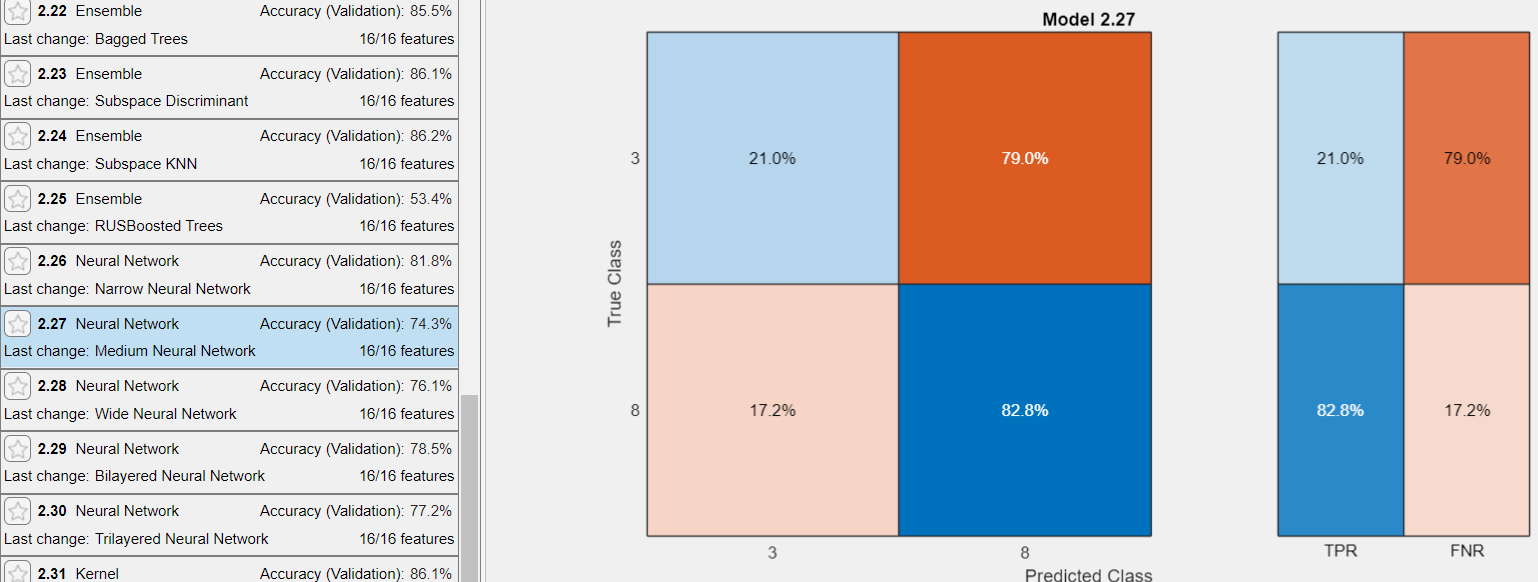

# **Classification of movement in the left upper extremity (LH):**

clear;clc;
% Upload .CSV file with the features of all EEG files
path = fullfile('./MILimbEEG/');%data folder
%allData = fLoad_EEG_csv(path,'AllDataRMS_motor_LH.csv');
allData = fLoad_EEG_csv(path,'AllDataRMS_imagery_LH.csv');
classificationLearner

# allowed_values = {'M2','M8'}; % M: motor tasks

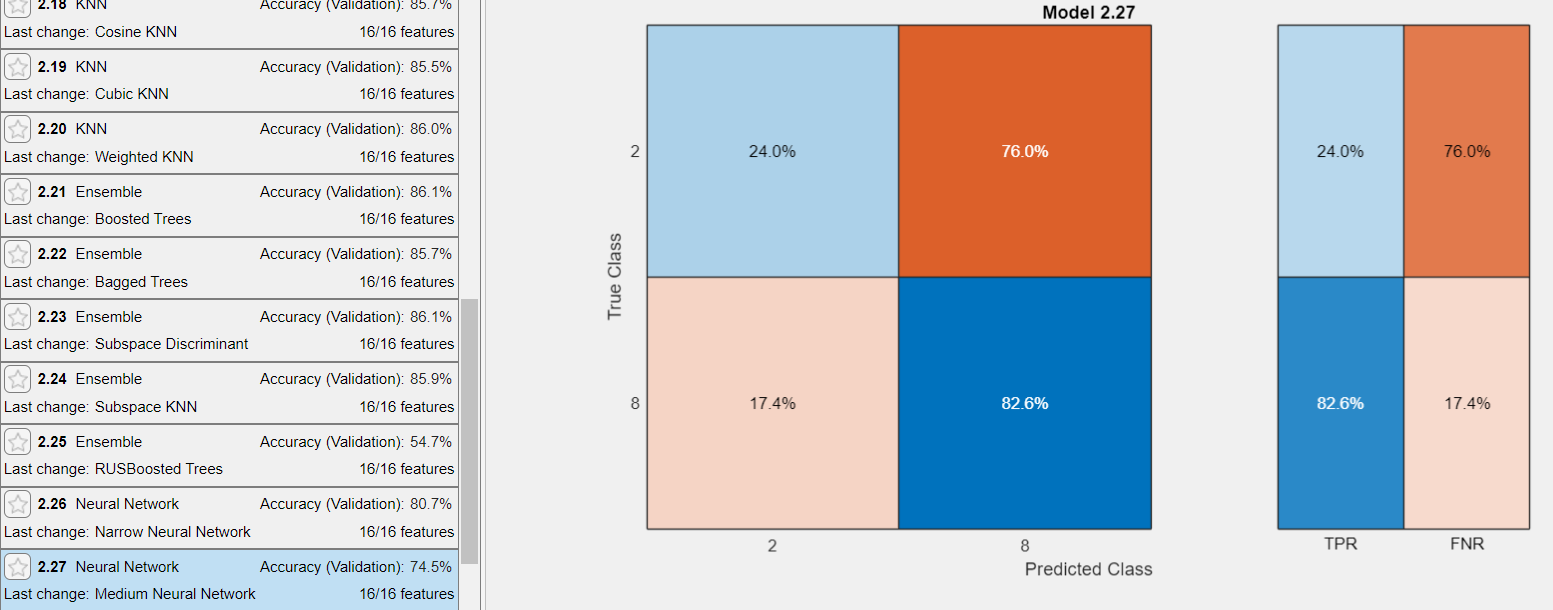

# allowed_values = {'I2','I8'}; % I: imagery tasks

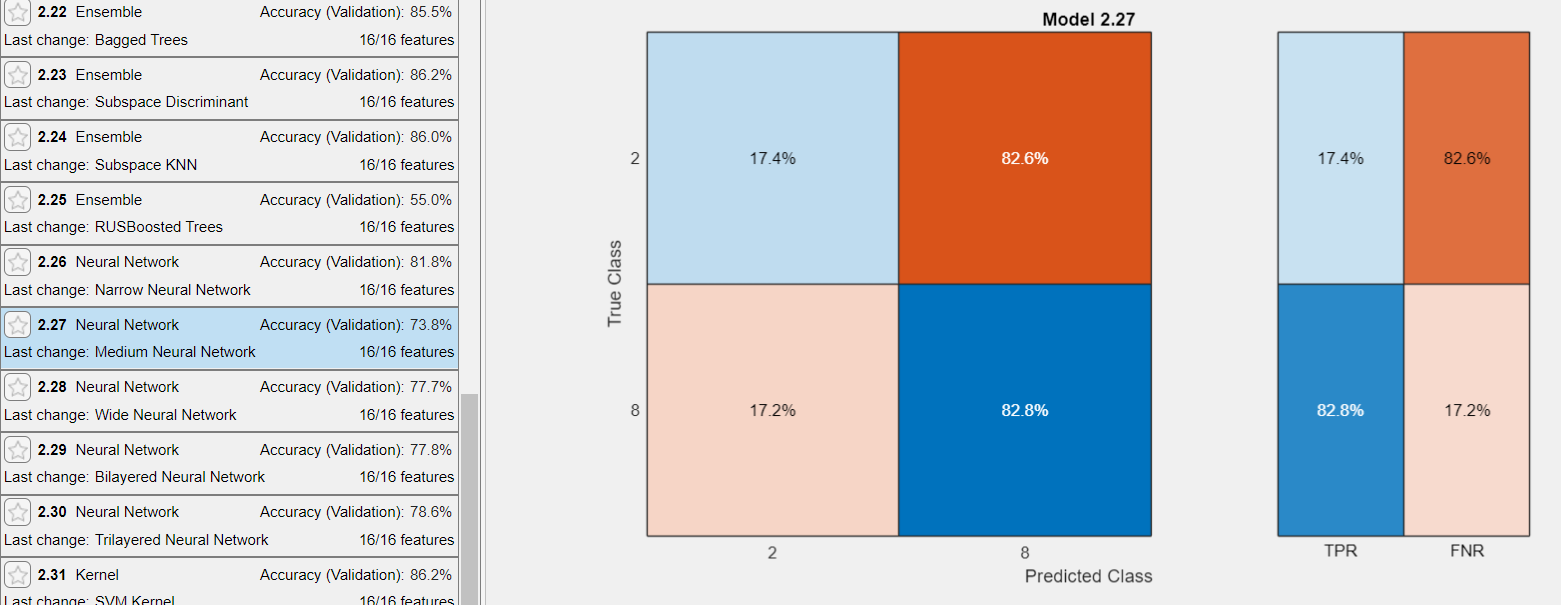

# **Classification of movement in the right and left upper extremity (RH & LH):**

clear;clc;
% Upload .CSV file with the features of all EEG files
path = fullfile('./MILimbEEG/');%data folder
%allData = fLoad_EEG_csv(path,'AllDataRMS_motor_RH_LH.csv');

allData = fLoad_EEG_csv(path,'AllDataRMS_imagery_RH_LH.csv');

classificationLearner


# allowed_values = {'M2','M3','M8'}; % M: motor tasks

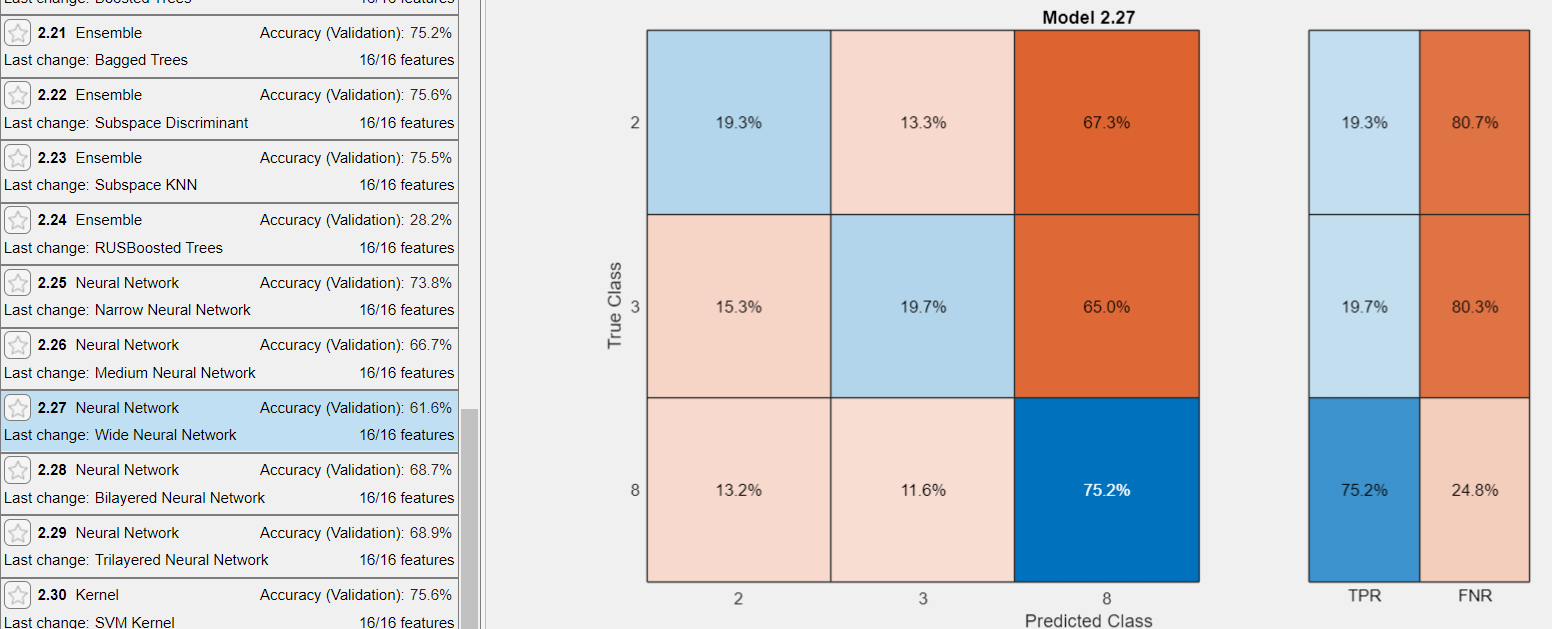

# allowed_values = {'I2','I3','I8'}; % I: imagery tasks